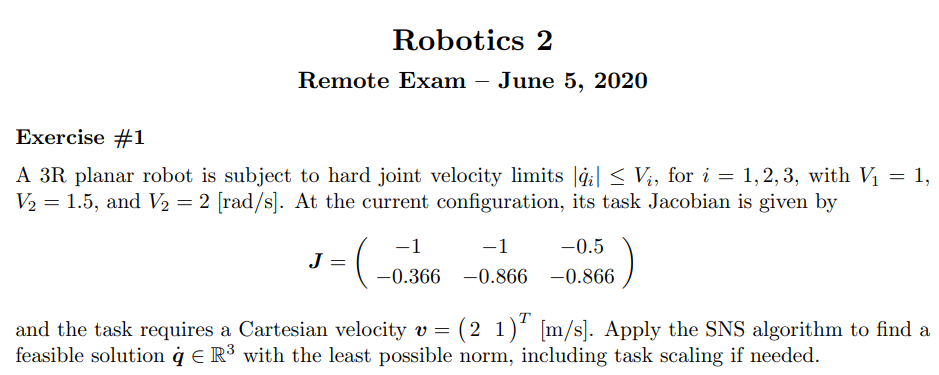

J = [-1 -1 -0.5; 
    -0.366 -0.866 -0.866;];
v = [2; 1;];
J_pinv = pinv(J)

J_pinv =    -1.1333    0.9309
   -0.2124   -0.3136
    0.6913   -1.2345


q_dot = J_pinv*v

q_dot =    -1.3357
   -0.7384
    0.1481



sns_result = SNS(v,{J},[-1,-1.5,-2],[1,1.5,2],0)

---- SNS for velocity
==========> Loop number: 1Result: 
   -1.3357
   -0.7384
    0.1481

Violating min: -3.357139e-01
Violating max: 0
--- Joint 1 exceeded bounds ==> -1.335714
--- Joint 1 now set at -1.000000 
==========> Loop number: 2Result: 
   -1.2679
    0.5358

Violating min: 0
Violating max: 0


sns_result =    -1.0000
   -1.2679
    0.5358


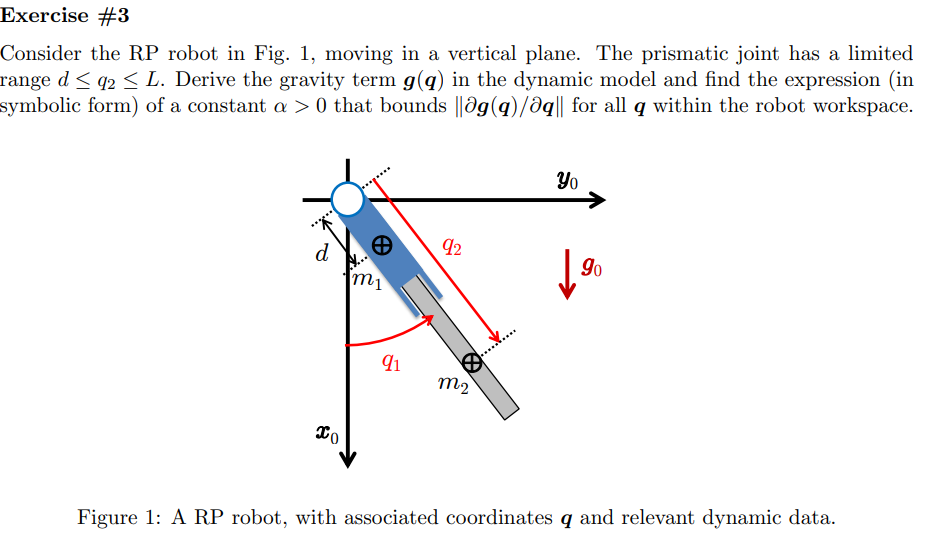

syms q1 q2 m_1 m_2 d g_0 real

U1 = m_1*g0*(d*cos(q1))

$$U1 = d\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

U2 = m_2*g0*(q2*cos(q1))

$$U2 = g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)$$

U = [U1+U2];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} -g_{0}\,\sin\left(q_{1}\right)\,\left(d\,m_{1}+m_{2}\,q_{2}\right)\\ g_{0}\,m_{2}\,\cos\left(q_{1}\right) \end{array}\right)$$

g_dot_q = jacobian(g_q, [q1, q2])

$$g\_dot\_q = \left(\begin{array}{cc} -g_{0}\,\cos\left(q_{1}\right)\,\left(d\,m_{1}+m_{2}\,q_{2}\right) & -g_{0}\,m_{2}\,\sin\left(q_{1}\right)\\ -g_{0}\,m_{2}\,\sin\left(q_{1}\right) & 0 \end{array}\right)$$

disp("EigenValue of g(q):")

EigenValue of g(q):


disp(simplify(sqrt(eig(g_dot_q.'*g_dot_q)),Steps=100))

$$\begin{array}{l} \left(\begin{array}{c} \sqrt{{g_{0}}^{2}\,{m_{2}}^{2}\,{\sin\left(q_{1}\right)}^{2}+\sigma_{2}+\sigma_{1}-\sigma_{4}-\sigma_{3}+d\,{g_{0}}^{2}\,m_{1}\,m_{2}\,q_{2}\,{\cos\left(q_{1}\right)}^{2}}\\ \sqrt{{g_{0}}^{2}\,{m_{2}}^{2}\,{\sin\left(q_{1}\right)}^{2}+\sigma_{2}+\sigma_{1}+\sigma_{4}+\sigma_{3}+d\,{g_{0}}^{2}\,m_{1}\,m_{2}\,q_{2}\,{\cos\left(q_{1}\right)}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{g_{0}}^{2}\,{m_{2}}^{2}\,{q_{2}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}\\ \sigma_{2}=\frac{d^{2}\,{g_{0}}^{2}\,{m_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}\\ \sigma_{3}=\frac{{g_{0}}^{2}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)\,\sigma_{5}}{2}\\ \sigma_{4}=\frac{d\,{g_{0}}^{2}\,m_{1}\,\cos\left(q_{1}\right)\,\sigma_{5}}{2}\\ \sigma_{5}=\sqrt{d^{2}\,{m_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}+2\,d\,m_{1}\,m_{2}\,q_{2}\,{\cos\left(q_{1}\right)}^{2}+{m_{2}}^{2}\,{q_{2}}^{2}\,{\cos\left(q_{1}\right)}^{2}+4\,{m_{2}}^{2}\,{\sin\left(q_{1}\right)}^{2}} \end{array}$$

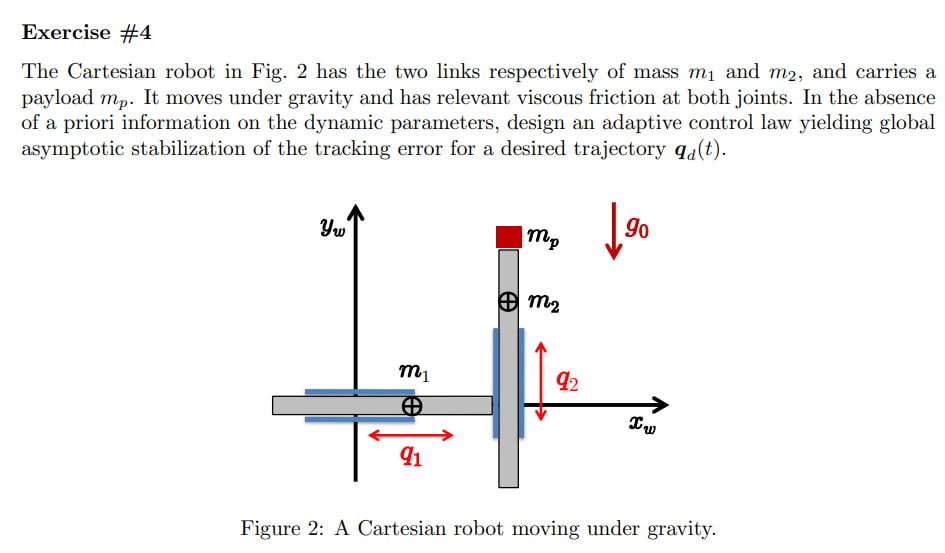

syms m_1 m_2 m_p q1 q2 q_dot_1 g0 real
syms a_1 a_2 a_3 a_4 real

T1 = 0.5*m_1*q_dot_1^2

$$T1 = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$


x = q1;
y = q2;
vx = diff(x,q1)*q_dot_1 + diff(x,q2)*q_dot_2

$$vx = {\dot{q}}_{1}$$

vy = diff(y,q1)*q_dot_1 + diff(y,q2)*q_dot_2

$$vy = {\dot{q}}_{2}$$

pro = [vx vy]*[vx; vy;]

$$pro = {{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}$$

T2 = 0.5*(m_2+m_p)*[vx vy]*[vx; vy;]

$$T2 = \left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right)\,{{\dot{q}}_{2}}^{2}$$

T = T1+T2

$$T = {{\dot{q}}_{1}}^{2}\,\left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right)+{{\dot{q}}_{2}}^{2}\,\left(\frac{m_{2}}{2}+\frac{m_{p}}{2}\right)+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);

M = [M11, M12;
     M21, M22;];

M = simplify(M)

$$M = \left(\begin{array}{cc} m_{1}+m_{2}+m_{p} & 0\\ 0 & m_{2}+m_{p} \end{array}\right)$$


% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


% gravity terms
U1 = 0;
U2 = (m_2+m_p)*g0*(q2);
U = [U1+U2];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} 0\\ g_{0}\,\left(m_{2}+m_{p}\right) \end{array}\right)$$


% Regressor matrix
M_para = [a_1 0; 0 a_2;]

$$M\_para = \left(\begin{array}{cc} a_{1} & 0\\ 0 & a_{2} \end{array}\right)$$

g_q_para = [0; g0*a_2;]

$$g\_q\_para = \left(\begin{array}{c} 0\\ a_{2}\,g_{0} \end{array}\right)$$

F_v_para = [a_3; a_4;]

$$F\_v\_para = \left(\begin{array}{c} a_{3}\\ a_{4} \end{array}\right)$$

q_dot = [q_dot_1; q_dot_2;]

$$q\_dot = \left(\begin{array}{c} {\dot{q}}_{1}\\ {\dot{q}}_{2} \end{array}\right)$$

dynamicModel = M_para*q_dot+g_q_para+F_v_para

$$dynamicModel = \left(\begin{array}{c} a_{3}+a_{1}\,{\dot{q}}_{1}\\ a_{4}+a_{2}\,g_{0}+a_{2}\,{\dot{q}}_{2} \end{array}\right)$$

Y = extract_Y_v3(dynamicModel, [a_1,a_2,a_3,a_4])

$$Y = \left(\begin{array}{cccc} {\dot{q}}_{1} & 0 & 1 & 0\\ 0 & g_{0}+{\dot{q}}_{2} & 0 & 1 \end{array}\right)$$

#### Utils function

function [new_values, old_values]= SNS(task, J_array, constraint_min, constraint_max, velocity_initial_condition)
    % This algorithm works for velocity and acceleration.
    % Change only equation to calculate desired task

    % PARAMETERS:
    %   - Task: task to achieve
    %   - J_array: array which contain the jacobian matrix. It is:
    %       - {J}       : For velocity
    %       - {J, dJ}   : For acceleration
    %   - constrain_min/max: Array containing constraints for each joint
    %   - velocity_initial_condition: Needed only for acceleration case, else you can put to 0 -> DEPRECATED

    % RETURNS:
    %   - new_values: Array containing the new values for the joints
    %   - old_values: Array containing the old values for the joints

    n_joint = length(constraint_min);
    task = reshape(task, length(task), 1);
    constraint_min = reshape(constraint_min, n_joint, 1);
    constraint_max = reshape(constraint_max, n_joint, 1);

    init_value = -999;
    new_values = linspace(init_value, init_value, n_joint);

    % Reshape the velocity_initial_condition to a column vector [num_joints x 1]
    if length(J_array) == 2
        velocity_initial_condition = reshape(velocity_initial_condition, n_joint, 1);
    end

    % Check if J_array is {J} or {J, dJ}
    % This means that we are working with velocity or acceleration respectively
    if isscalar(J_array)
        disp("---- SNS for velocity")
        J = J_array{1};
        type_task = 'v';
    elseif length(J_array) == 2
        disp("---- SNS for acceleration")
        J = J_array{1};
        dJ = J_array{2};
        type_task = 'a';
    else
        disp("Error: J_array = {J, dJ} or J_array = {J}")
        return
    end

    % Check based on the type of task
    if type_task == 'v'
        old_values = pinv(J)*task;
    elseif type_task == 'a'
        old_values = pinv(J)*(task - dJ*velocity_initial_condition);
    end

    for i = 1:n_joint
        fprintf("==========> Loop number: %d", i)
        if type_task == 'v'
            result = pinv(J)*task;
        elseif type_task == 'a'
            result = pinv(J)*(task - dJ*velocity_initial_condition);
        end

        result = reshape(result, n_joint-i+1, 1);
        disp("Result: ")
        disp(result)

        % picking maximum violating constraint for max
        violating_max_logical = logical(result > constraint_max);
        violating_max_value = max(dot(result - constraint_max, violating_max_logical));
        
        % picking maximum violating constraint for min
        violating_min_logical = logical(result < constraint_min);
        violating_min_value = min(dot(result - constraint_min, violating_min_logical));

        % Print the violating constraints
        fprintf("Violating min: %d\n", violating_min_value)
        fprintf("Violating max: %d\n", violating_max_value)

        if all(~violating_min_logical) && all(~violating_max_logical)
            logic_subs = logical(new_values == init_value);
            
            counter_subs = 1;
            % Substitute the value in the new_values array
            for j = 1:length(new_values)
                if logic_subs(j) == 1
                    new_values(j) = result(counter_subs);
                    counter_subs = counter_subs + 1;
                end
                
            end
            
            % Reshape the new_values array to a column vector [num_joints x 1]
            new_values = reshape(new_values, n_joint, 1);
            break
        end
        
        % Check which constraint is violating the most
        if abs(violating_min_value) > abs(violating_max_value)
            violating_joint_index = find( (result-constraint_min) == violating_min_value );
            violation_type = 'violating_min';
        else
            violating_joint_index = find( (result-constraint_max) == violating_max_value );
            violation_type = 'violating_max';
        end

        fprintf("--- Joint %d exceeded bounds ==> %f\n", violating_joint_index, result(violating_joint_index));
        
        if strcmp(violation_type, 'violating_min')
            new_values(violating_joint_index) = constraint_min(violating_joint_index);
        else
            new_values(violating_joint_index) = constraint_max(violating_joint_index);
        end
        fprintf("--- Joint %d now set at %f \n", violating_joint_index, new_values(violating_joint_index))

        if type_task == 'v'
            selected_J = J(:, violating_joint_index);
            actual_velocity = new_values(violating_joint_index);
            task = task - selected_J*actual_velocity;

        elseif type_task == 'a'
            selected_J = J(:, violating_joint_index);

            actual_acceleration = new_values(violating_joint_index);

            task = task - selected_J*actual_acceleration;
 
            dJ(:,violating_joint_index) = [];
            velocity_initial_condition(violating_joint_index) = [];
        end
        
        % Empty all the values related to the violating joint
        J(:, violating_joint_index) = [];
        constraint_max(violating_joint_index) = [];
        constraint_min(violating_joint_index) = [];
     end
end

function Y = extract_Y_v3(Ya, dynamic_symbols)
    % M: inertia matrix
    % C: christoffel matrix
    % G: potential enrgy matrix
    % joint_acceleration: array with joint acceleration
    % this four items are use to build dynamic model

    % dynamic_model: in the form M*ddq + C + G
    % dynamic_coefficient: an array which contain symbol like [ m1+m3 I2
    % ...]
    % dynamic_symbols: how substitute coefficient, so [a1 a2 ... a_n]
    
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i=1:Y_columns
        
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;

        Yi = subs(Ya, dynamic_symbols, subs_array);

        Y = [Y, Yi];
    end
    
end